# Frequency Sampling FIR Filter Design Experiments

## FFT-based Design

### Bandpass Filter via FFT sampling


$$$H_d \left(\omega \right)=\left\lbrace \begin{array}{ll}
1, & \frac{\pi }{4} \lt \left|\omega+2\pi k\right| \leq \frac{\pi}{2}\\
0, & \text{else}
\end{array}\right.$$$


#### Create desired response:

clear;
N = 128;
omega = 2*pi/N*(0:N-1); % N points around the unit circle

% Allocate memory for Freq Resp (will fill in below)
Hd = zeros(1,N);  

% Create filter, being careful to handle negative frequencies correctly
ipassband_pos = (omega > pi/4)        & (omega <= pi/2);
ipassband_neg = (omega < 2*pi - pi/4) & (omega >= 2*pi - pi/2);
Hd(ipassband_pos | ipassband_neg) = 1;

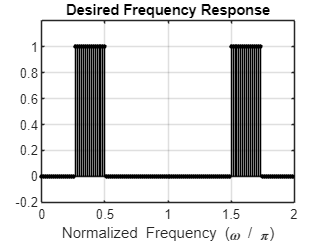

% Plot desired response
figure,stem(omega/pi, Hd, "k", "filled",markersize=2.5); grid;
ylim([-0.2 1.2]);
title('Desired Frequency Response')
xlabel('Normalized Frequency (\omega / \pi)')

#### Determine filter coefficients

Take IFFT to find coefficients:

hper = ifft(Hd);
n = 0 : N-1;

Then circulaly shift the result to account for periodicity:

h = fftshift(hper);

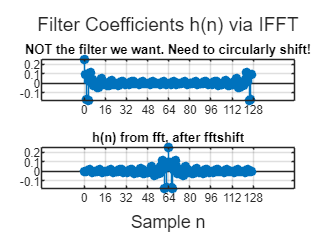

% Plot the two impulse responses
figure;
tl = tiledlayout(2,1);
title(tl,"Filter Coefficients h(n) via IFFT");
xlabel(tl,"Sample n")

% Raw IFFT impulse response
nexttile, stem(n,hper,"filled"), title ('NOT the filter we want. Need to circularly shift!')
xlim([0 N-1] + round(N/4)*[-1 1]);
xticks(0:16:N); grid;

% Circularly shifted impulse response
nexttile, stem(n,h,"filled"), title ('h(n) from fft, after fftshift')
xlim([0 N-1] + round(N/4)*[-1 1]);
xticks(0:16:N); grid;

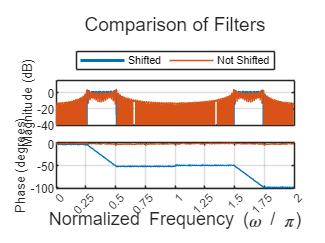

% Compare frequency responses
[Hper,wper] = freqz(hper,1,"whole");
[H,w] = freqz(h,1,"whole");

% Plots
%   Note: eps is included in angle because angle(0) is not well-defined. If
%         omitted, plots will be slightly erratic, though more-or-less
%         correct
mag_fcn = @(H) 20*log10(abs(H));
phase_fcn = @(H) unwrap(angle(H+eps)); 

figure;
tl = tiledlayout(2,1,TileSpacing="compact"); 
title(tl,"Comparison of Filters"); xlabel(tl,'Normalized Frequency (\omega / \pi)')
ax = nexttile; hl = plot(w/pi, mag_fcn([H Hper])); hl(1).LineWidth = 2; 
xticks([]); ylabel("Magnitude (dB)"); ylim([-40 15]); grid;

nexttile; plot(w/pi, phase_fcn([H Hper])); grid;
xticks(0:0.25:2); ylabel("Phase (degrees)")

legend(ax,{"Shifted","Not Shifted"},Location="NorthOutside",Orientation="Horizontal")

Note that linear convolution with the unshifted filter will create "hard" transients at the edges due to the abrupt change from zero near the edges.  This gives rise to the difference between the two results.  Also observe that the values of the magnitude response of the unshifted filter is equal to our desired value of 1 at the chosen frequency samples, but are clearly different in-between those samples.  The next bit of code zooms in to see this.

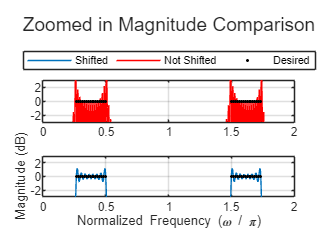

% Zoom in on magnitude plot
figure;
tl = tiledlayout(2,1);
title(tl,"Zoomed in Magnitude Comparison")
ax1 = nexttile; 
hl1 = plot(w/pi, 20*log10(abs(Hper)),'r', ...
    omega/pi, 20*log10(abs(Hd)), 'k.'); grid; xlim([0 2]); 
ax2 = nexttile; 
hl2 = plot(w/pi, 20*log10(abs(H)), omega/pi,20*log10(abs(Hd)),'k.'); grid;
xlabel("Normalized Frequency (\omega / \pi)"); ylabel("Magnitude (dB)"); 
xlim([0 2]); ylim([ax1 ax2],[-3 3]);
legend(ax1,[hl2(1) hl1(1) hl1(2)],{"Shifted","Not Shifted","Desired"},...
    Location="NorthOutside",Orientation="Horizontal")

Instead of using `fftshift`, we could have designed the correct filter from the start by adding a linear phase term to the desired filter


$$$H_d \left(\omega \right)=\left\lbrace \begin{array}{ll}
e^{-j\frac{M}{2}\omega}, & \frac{\pi }{4} \lt \left|\omega+2\pi k\right| \leq \frac{\pi}{2} \\
0, & \text{else}
\end{array}\right.$$$


where $M$ is the filter order. This just implements the circular shift in the frequency domain so that the inverse transform result will not require an addition circular shift.  Like above, one needs to handle the negative frequency regions carefully. You will look at this more in one of the projects.

### Design an Unusual filter via FFT Sampling

Picking $\sin^4(\omega)$ for fun. Could be anything.


$$$H_d \left(\omega \right)=\left\lbrace \begin{array}{ll}
\sin^4(\omega), & \left|\omega+2\pi k\right| \leq \frac{\pi}{4}\\
0, & 
\end{array}\right.$$$


#### Create desired response:

clear;
N = 64;
omega = 2*pi/N*(0:N-1); % N points around the unit circle

% Allocate memory for Freq Resp (will fill in below)
Hd = zeros(1,N);  

% Create filter, being careful to handle negative frequencies correctly
ipassband = (omega <= pi/4) | (omega >= 2*pi - pi/4);
Hd(ipassband) = sin(omega(ipassband)).^4;

% Plot the response
figure,stem(omega/pi, Hd, "k", "filled",markersize=2.5); grid;
ylim([-0.2 1.2]);
title('Desired Unusual Frequency Response')
xlabel('\omega / \pi (normalized radians)')

#### Determine filter coefficients

Take DFT and circularly shift to account for periodicity of FFT.  In this case, there is some numerical round-off and the desired response was not perfectly conjugate symmetric. Therefore, the time-domain samples were not real. We just ignore the really small ($\le \;1\ldotp 6\times {10}^{-17}$) values.

h = fftshift( ifft(Hd) ); 
n = 0 : N-1;

% Need to take out tiny imag part, some round-off in sin()^4 calculations
% so it was not exactly conjugate symmetric
disp("Max(imag part) = " + max(abs(imag(h))));

Max(imag part) = 1.5741e-17


h = real(h);

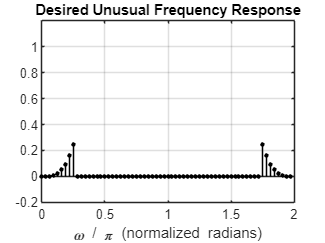

% Plot impulse and frequency response
title(tiledlayout(3,1),"Unusual Filter Design");

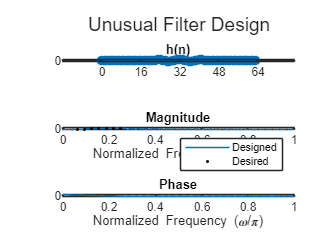

nexttile; stem(n,h,"filled"), title('h(n)')
xlim([0 N-1] + round(N/4)*[-1 1]);
xticks(0:16:N); grid;

[H,w] = freqz(h,1);
nexttile; plot(w/pi,20*log10(abs(H))); axis([0 1 -60 10]); grid;
hold on; plot(omega/pi, 20*log10(abs(Hd)), 'k.'); hold off;
title("Magnitude"); ylabel("Magnitude (dB)")
xlabel("Normalized Frequency (\omega/\pi)");
legend({"Designed","Desired"})
nexttile; plot(w/pi,unwrap(angle(H+eps))*180/pi); grid on;
title("Phase"); ylabel("Phase (degrees)");
xlabel("Normalized Frequency (\omega/\pi)")

## Matlab's FIR2 (Python FIRWIN2)

### Lowpass via FIR2 - with and without windowing

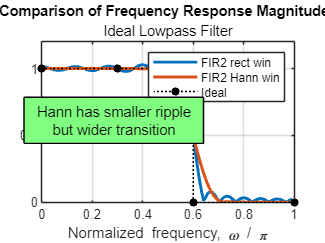

f = [0 0.3 0.5 0.6 0.6 1]; 
m = [1 1 1 1 0 0];
br = fir2(30,f,m,rectwin(31));
bh = fir2(30,f,m,hann(31));
[Hr,~] = freqz(br,1,128);
[Hh,w] = freqz(bh,1,128);

figure;
plot(w/pi,abs([Hr Hh]),LineWidth=2); hold on;
plot(f,m,'k:o',MarkerFaceColor='k',MarkerSize=5); hold off;
xlabel('Normalized frequency, \omega / \pi'); grid;
legend("FIR2 rect win","FIR2 Hann win","Ideal")
title('Comparison of Frequency Response Magnitudes')
subtitle("Ideal Lowpass Filter")
annotation("textbox",[0.2 0.4 0.3 0.2],...
    String={"Hann has smaller ripple","but wider transition"},...
    HorizontalAlignment="center",FitBoxToText="on",BackgroundColor=[0.5 1 0.5])

### Lowpass via FIR2 - with "don't care" region

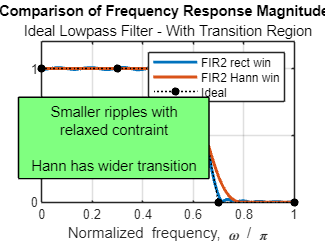

f = [0 0.3 0.5 0.6 0.7 1]; 
m = [1 1 1 1 0 0];
br = fir2(30,f,m,rectwin(31));
bh = fir2(30,f,m,hann(31));
[Hr,~] = freqz(br,1,128);
[Hh,w] = freqz(bh,1,128);

plot(w/pi,abs([Hr Hh]),LineWidth=2); hold on;
plot(f,m,'k:o',MarkerFaceColor='k',MarkerSize=5); hold off;
xlabel('Normalized frequency, \omega / \pi'); grid;
legend("FIR2 rect win","FIR2 Hann win","Ideal")
title('Comparison of Frequency Response Magnitudes')
subtitle("Ideal Lowpass Filter - With Transition Region")
annotation("textbox",[0.2 0.4 0.3 0.2],...
    String={"Smaller ripples with","relaxed contraint","","Hann has wider transition"},...
    HorizontalAlignment="center",FitBoxToText="on",BackgroundColor=[0.5 1 0.5])

### Arbitrary Response via FIR2

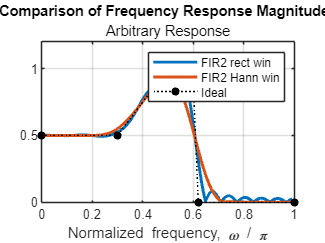

f = [0 0.3 0.5 0.6 0.62 1]; 
m = [.5 .5 1 .9 0 0];

br = fir2(30,f,m,rectwin(31));
bh = fir2(30,f,m,hann(31));
[Hr,~] = freqz(br,1,128);
[Hh,w] = freqz(bh,1,128);

plot(w/pi,abs([Hr Hh]),LineWidth=2); hold on;
plot(f,m,'k:o',MarkerFaceColor='k',MarkerSize=5); hold off;
xlabel('Normalized frequency, \omega / \pi'); grid;
legend("FIR2 rect win","FIR2 Hann win","Ideal")
title('Comparison of Frequency Response Magnitudes')
subtitle("Arbitrary Response")